## Multilevel Subband Analysis

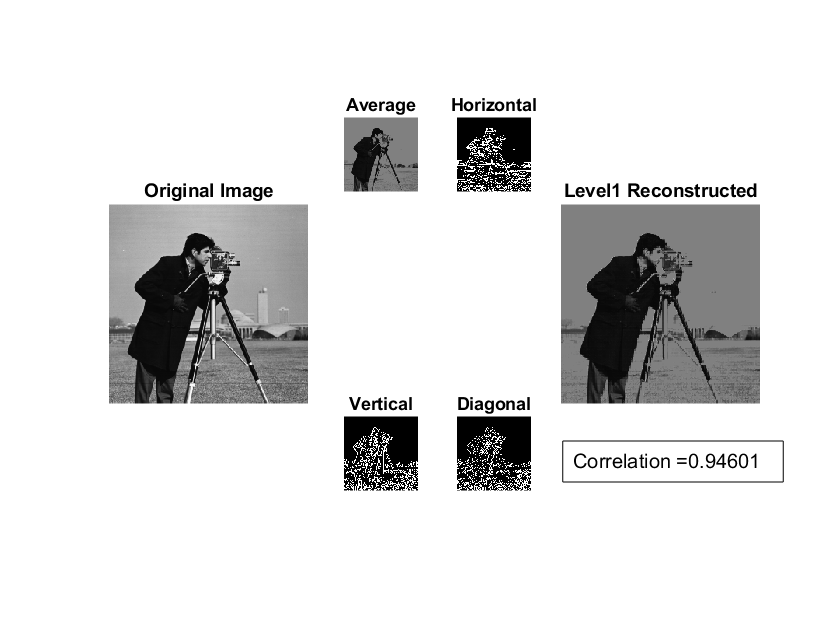

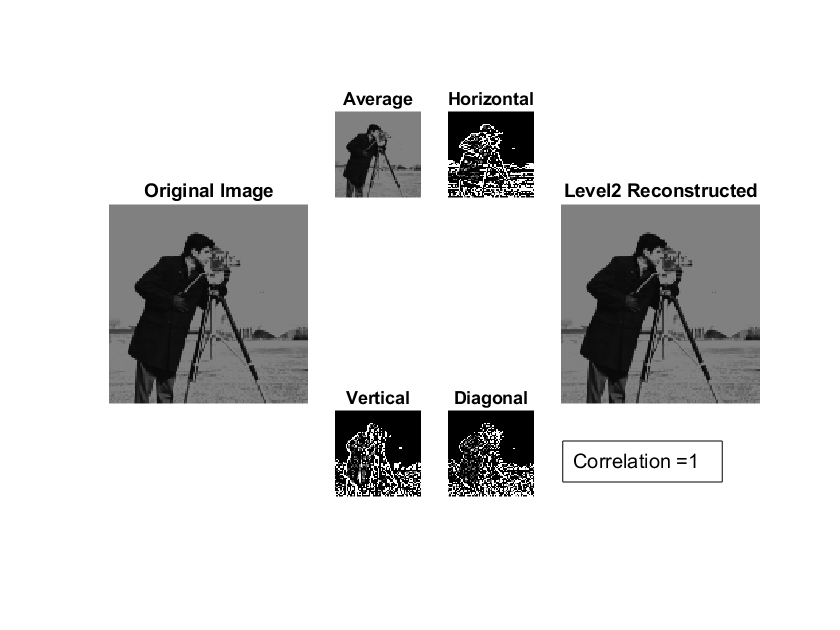

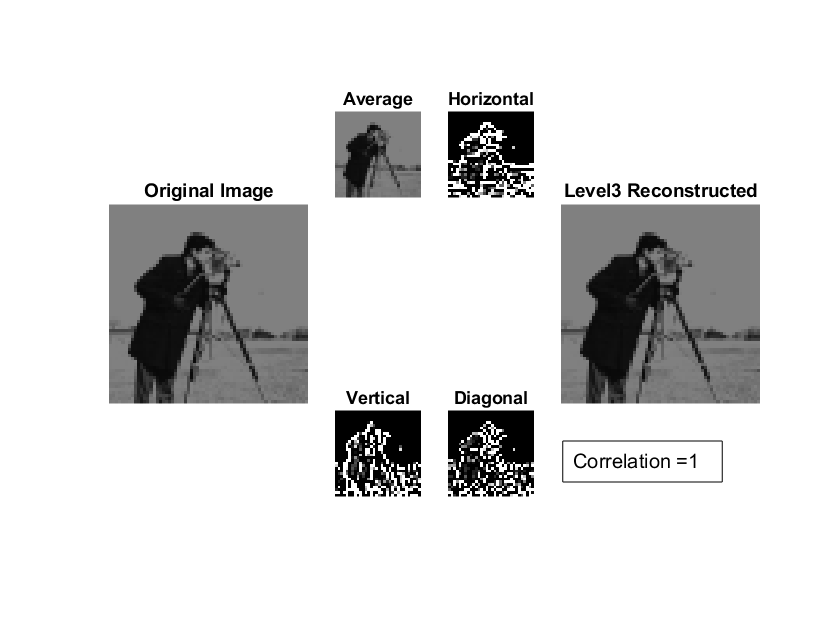

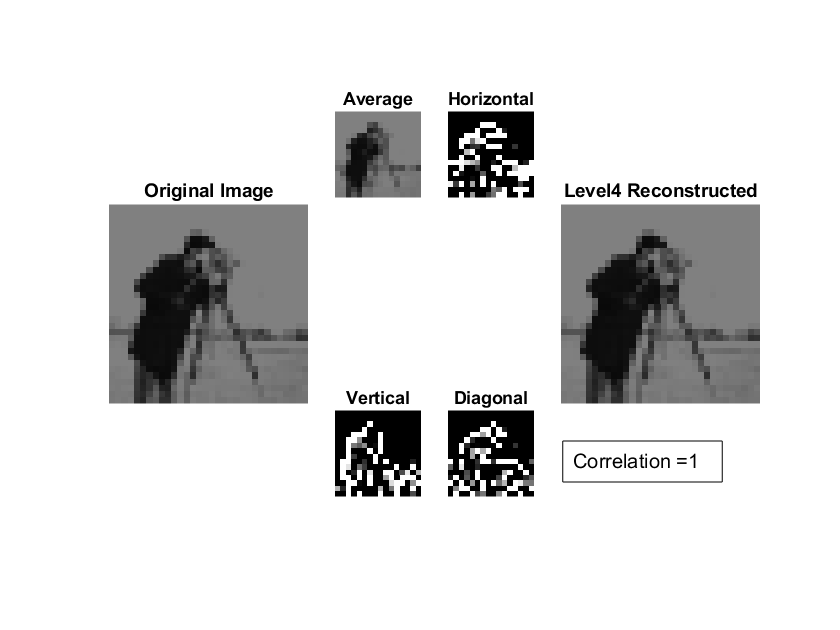

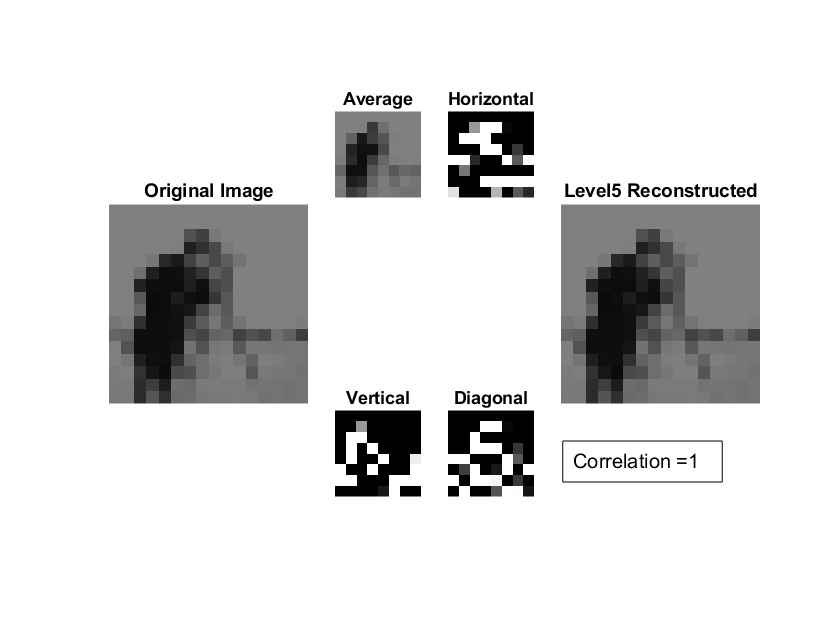

clear;
I = imread('cameraman.tif');
hwt(I,5);

## Nulling Wavelet Coefficients

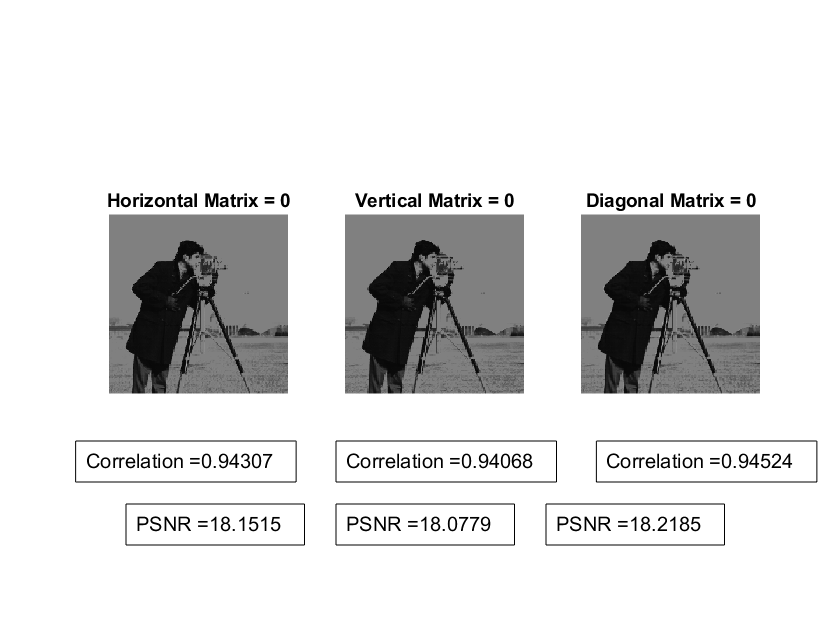

clear;
I = imread('cameraman.tif');
[x,y] = size(I);
[A,H,V,D] = forward_haar_wavelet(I);

% Zeroing H-subband
reconstructed_1 = uint8(inverse_haar_wavelet(A,zeros(x,y),V,D));
[c1, p1] = quantify_compression(I, reconstructed_1);
figure;
subplot(1,3,1); imshow(reconstructed_1); title('Horizontal Matrix = 0');
annotation('textbox',[0.09 0.2 0.1 0.1],'String',...
    strcat('Correlation = ', num2str(c1)),'FitBoxToText','on')
annotation('textbox',[0.15 0.1 0.1 0.1],'String',...
    strcat('PSNR = ', num2str(p1)),'FitBoxToText','on')

% Zeroing V-subband
reconstructed_2 = uint8(inverse_haar_wavelet(A,H,zeros(x,y),D));
[c2, p2] = quantify_compression(I, reconstructed_2);
subplot(1,3,2); imshow(reconstructed_2); title('Vertical Matrix = 0');
annotation('textbox',[0.4 0.2 0.1 0.1],'String',...
    strcat('Correlation = ', num2str(c2)),'FitBoxToText','on')
annotation('textbox',[0.4 0.1 0.1 0.1],'String',...
    strcat('PSNR = ', num2str(p2)),'FitBoxToText','on')

% Zeroing D-subband
reconstructed_3 = uint8(inverse_haar_wavelet(A,H,V,zeros(x,y)));
[c3, p3] = quantify_compression(I, reconstructed_3);
subplot(1,3,3); imshow(reconstructed_3); title('Diagonal Matrix = 0');
annotation('textbox',[0.71 0.2 0.1 0.1],'String',...
    strcat('Correlation = ', num2str(c3)),'FitBoxToText','on')
annotation('textbox',[0.65 0.1 0.1 0.1],'String',...
    strcat('PSNR = ', num2str(p3)),'FitBoxToText','on')

# External Functions

function hwt(I, level)
% Perform multi-level haar wavelet transform on multiple levels

if log2(size(I,1))-1 < level
    error('the required level analysis is not possible')
end

for i=1:level
    if exist('A','var')
        [A,~,~,~] = one_level_hwt(A);
    else
        [A,~,~,~] = one_level_hwt(I);
    end
    title(strcat('Level ',num2str(i), ' Reconstructed'));
end

end

function [A,H,V,D] = one_level_hwt(I)
% 1. Produce subbands of one level forward haar wavelet transform
% 2. Reconstruct image using one level inverse haar wavelet transform
% 3. Quantify compression quality by measuring the correlation

[A,H,V,D] = forward_haar_wavelet(I);

figure;
subplot(2,6,[1,2,7,8]); imshow(uint8(I));
title('Original Image');
subplot(2,6,3); imshow(uint8(A));
title('Average');
subplot(2,6,4); imshow(H);
title('Horizontal');
subplot(2,6,9); imshow(V);
title('Vertical');
subplot(2,6,10); imshow(D);
title('Diagonal');

reconstructed = inverse_haar_wavelet(A,H,V,D);
subplot(2,6,[5,6,11,12]);
imshow(uint8(reconstructed));
[c, ~] = quantify_compression(I, reconstructed);
annotation('textbox',[0.67 0.2 0.1 0.1],'String',strcat('Correlation = ', num2str(c)),'FitBoxToText','on')

end

function [A,H,V,D] = forward_haar_wavelet(I)
% Forward Haar Wavelet 2D Transform

[x,y] = size(I);
x = uint8(x/2);
y = uint8(y/2);

A = zeros(x,y);
H = zeros(x,y);
V = zeros(x,y);
D = zeros(x,y);

for i=1:x
    for j=1:y
        a = I(2*i-1,2*j-1);
        b = I(2*i-1,2*j);
        c = I(2*i,2*j-1);
        d = I(2*i,2*j);
        A(i,j) = ((a+b)/2 + (c+d)/2)/2;
        H(i,j) = ((a+b)/2 - (c+d)/2)/2;
        V(i,j) = ((a+c)/2 - (b+d)/2)/2;
        D(i,j) = ((a+d)/2 - (b+c)/2)/2;
    end
end

end

function I = inverse_haar_wavelet(A,H,V,D)
% Inverse Haar Wavelet 2D Transform

[x,y] = size(A);
I = zeros(x*2,y*2);

for i=1:x
    for j=1:y
        a = A(i,j)+H(i,j)+V(i,j)+D(i,j);
        b = A(i,j)+H(i,j)-V(i,j)-D(i,j);
        c = A(i,j)-H(i,j)+V(i,j)-D(i,j);
        d = A(i,j)-H(i,j)-V(i,j)+D(i,j);
        I(2*i-1,2*j-1) = a;
        I(2*i-1,2*j) = b;
        I(2*i,2*j-1) = c;
        I(2*i,2*j) = d;
    end
end

end

function out = psnr(a, b)
% Calculate PSNR

if (size(a)~=size(b))
    error('images do not comply')
end

[m,n] = size(a);
mse = sum(sum((a-b).^2))./(m*n);
out = 20 * log10(255/sqrt(mse));

end

function [C, P] = quantify_compression(I, reconstructed)
% Measure Compression Performance: Correlation and PSNR

C = corr2(double(I),double(reconstructed));
P = psnr(double(I),double(reconstructed));

end